# Icons Command-line Interface

Icons add-on allows you to use all its features without [companion app](matlab:IconsApp).

## Main features

### Create object

Start with creating an object of `Icon` class

i = Icon

i =   Icon with properties:

     Name: []
    Color: []
    Scale: 1

All Properties, Methods

Explore properties and methods of the created object.

### Search for icon

Use `searh` method to find desired icon by partial name

is = i.search('matlab')

is = 2×2 table
           Name              Pack    
    __________________    ___________

    "mw-matlab-laptop"    "MathWorks"
    "mw-matlab"           "MathWorks"


### Select icon

Choose desired icon with `use` method

i.use('mw-matlab')

ans =   Icon with properties:

     Name: 'mw-matlab'
    Color: []
    Scale: 1

All Properties, Methods

### Change icon's color

To change color of icon use `setColor` method

i.setColor([0 1 0]); % set color in MATLAB RGB format
i.setColor('red'); % set color by color name
i.setColor('#E67E22'); % set color in HEX format

Pick desired color from MATLAB palette using `pickColor`

i.pickColor

ans =   Icon with properties:

     Name: 'mw-matlab'
    Color: [1 0.4118 0.1608]
    Scale: 1

All Properties, Methods

### Show icon

To examine icon use `show` method

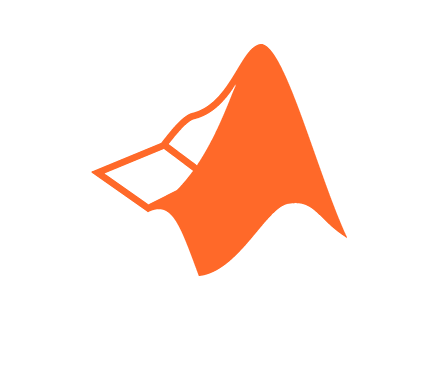

i.show

### Save icon

To save icon in current folder use `save` method

i.save

To save icon in specified folder pass folder path to `save` method

i.save(pwd)

### Open documentation

To open Icons documentation use `doc` static method

Icon.doc

## Additional Features

### Get packs and icons

To get available icon packs use `getPacks` method

i.getPacks

ans = 4×1 string array
    "FontAwesome"
    "MaterialDesign"
    "MathWorks"
    "MyIcons"


To get a list of available icons use `getIcons` method

is = i.getIcons;
height(is) % get number of icons

ans = 1797

head(is) % get first 8 icons

ans = 8×2 table
           Name                Pack     
    ___________________    _____________

    "fa-500px"             "FontAwesome"
    "fa-address-book-o"    "FontAwesome"
    "fa-address-book"      "FontAwesome"
    "fa-address-card-o"    "FontAwesome"
    "fa-address-card"      "FontAwesome"
    "fa-adjust"            "FontAwesome"
    "fa-adn"               "FontAwesome"
    "fa-align-center"      "FontAwesome"


### Get predefined colors

Get list of predefined icon colors with `getColors` method

cs = i.getColors;
height(cs) % number of predefined colors

ans = 144

Show list of available colors in figure with `showColors`

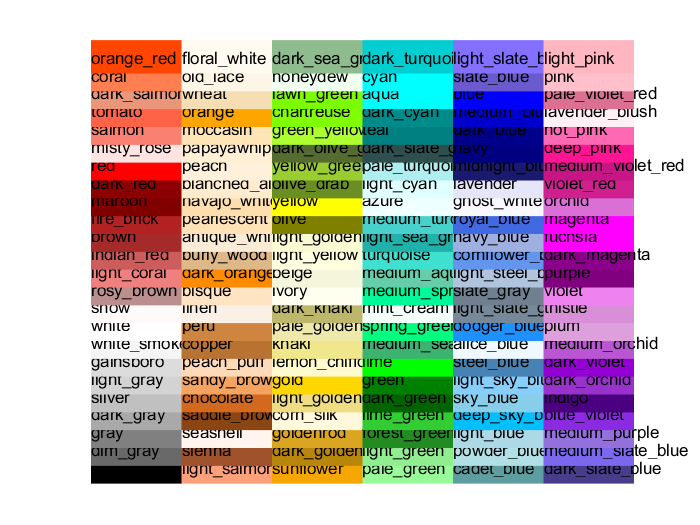

i.showColors % execute it in Command Window ant toggle to full screen

### Change icon scale

You can change size of icon using `setScale`

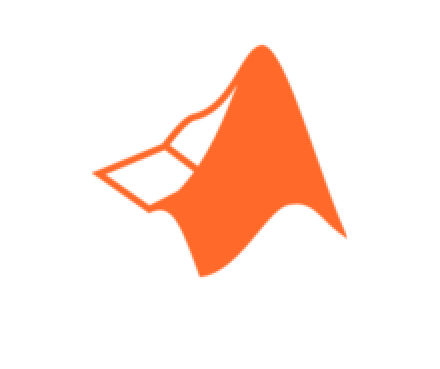

i.setScale(0.5); % downscale icon
i.show

### Open library

To open icons library execute `lib` method

i.lib